% clear variables in workspace and close all figures
clearvars; close all;

% reading the data
% data = readtimetable('../Datasets/Saint John/SaintJohnEnergy.xlsx');
data = readtimetable('../Datasets/Ontario/TorontoIESO.xlsx');

TR = timerange('2010-01-01','2019-12-31 23:00:00', "closed");
data = data(TR, :);   % new total dataset

% detecting and removing outliers using Hampel filter
data.DemandMW = hampel(data.DemandMW);
data.Temperature = hampel(data.Temperature);
data.Humidity = hampel(data.Humidity);
data.Dewpoint = hampel(data.Dewpoint);
data.WindDirection = hampel(data.WindDirection);
data.WindSpeed = hampel(data.WindSpeed);

% Normalizing the variables

% y = (x - min) / (max - min)
tmp = timetable2table(data);
maxdp = max(table2array(tmp(:, 2:end)));    % takes the max and min of each variable in the dataset
mindp = min(table2array(tmp(:, 2:end)));
tmp.DateTime = [];
normalize = (table2array(tmp) - mindp) ./ (maxdp - mindp);

% creating the normalized dataset
ndata = data;
ndata.DemandMW = normalize(:, 1);
ndata.Temperature = normalize(:, 2);
ndata.Humidity = normalize(:, 3);
ndata.Dewpoint = normalize(:, 4);
ndata.WindDirection = normalize(:, 5);
ndata.WindSpeed = normalize(:, 6);

clearvars -except data ndata mindp maxdp

TR = timerange('2010-01-01','2019-01-01');  % All of 2010 - 2018
trainvald = ndata(TR, :);   % training data

TR = timerange('2019-01-01','2020-01-01');  % All of 2019
testd = ndata(TR, :);   % testing data

## The Seasonal Naive Approach

### Predict the test dataset

% Takes the actual demand of the previous week
TR = testd.DateTime - days(7);
yNaive = ndata.DemandMW(TR);

% Denormalization
actuals = testd.DemandMW * (maxdp(1) - mindp(1)) + mindp(1);
yNaive = yNaive * (maxdp(1) - mindp(1)) + mindp(1);

### Calculate errors

[Metrics, errors, AEs, APEs, MAPE] = ErrorMetrics(actuals, yNaive);

Metrics

Metrics = 6×2 table
                   Metrics                       Var2   
    ______________________________________    __________

    {'MAPE - Mean Absolute Percent Error'}        6.0913
    {'ME - Mean Error'                   }        1.6663
    {'MAE - Mean Absolute Error'         }        350.36
    {'MSE - Mean Squared Error'          }    2.3822e+05
    {'RMSE - Root Mean Squared Error'    }        488.07
    {'Standard Deviation'                }         488.1


### Plots of the Test dataset

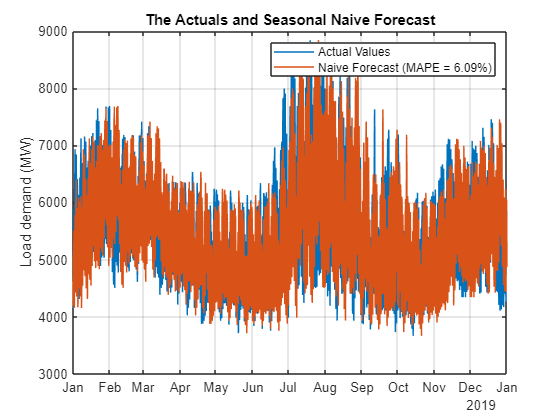

figure;

% plot actual values
plot(testd.DateTime, actuals, 'DisplayName','Actual Values')
title('The Actuals and Seasonal Naive Forecast')
ylabel('Load demand (MW)')
grid on; 
hold on;

% plot naive forecast
DisplayName = num2str(MAPE, 'Naive Forecast (MAPE = %.2f%%)');
plot(testd.DateTime, yNaive, 'DisplayName', DisplayName)
legend('show')

[DailyPeak]= PeakDetection(testd.DateTime, actuals, yNaive);
DailyPeak

DailyPeak = 365×7 timetable
       Time        ActPkHr    ActPk    PredPkHr    PredPk    TimeDiff    ValueDiff      APEs  
    ___________    _______    _____    ________    ______    ________    _________    ________

    01-Jan-2019      18       5901        17        5510        -1          -391         6.626
    02-Jan-2019      17       6933        17        5788         0         -1145        16.515
    03-Jan-2019      17       6841        17        6408         0          -433        6.3295
    04-Jan-2019      17       6410        17        5904         0          -506        7.8939
    05-Jan-2019      17       6133        18

% Overall MAPE
DayPk_MAPE = mean(DailyPeak.APEs)

DayPk_MAPE = 6.1847

% gives you the hours, minutes, seconds
DayPk_TimeDiff_MBE = round(minutes(hours(mean(DailyPeak.TimeDiff)))) 

DayPk_TimeDiff_MBE = 0

DayPk_TimeDiff_MAE = round(minutes(hours(mean(abs(DailyPeak.TimeDiff)))))

DayPk_TimeDiff_MAE = 92

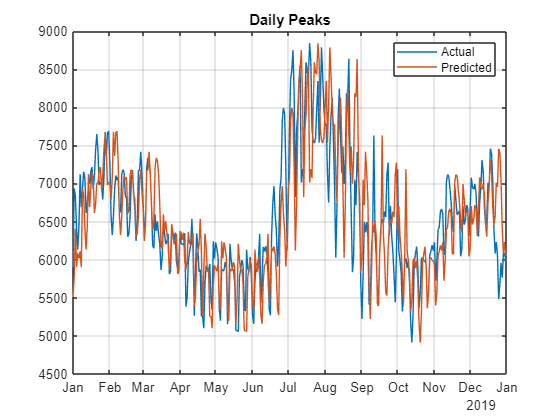

% Plots of the daily peaks
figure;
plot(DailyPeak.Time, DailyPeak.ActPk, 'DisplayName','Actual')
title('Daily Peaks')
hold on
plot(DailyPeak.Time, DailyPeak.PredPk, 'DisplayName', 'Predicted')
grid on
legend('show')

## Performance Analysis of the Algorithm

dt = testd.DateTime;    % DateTime of the test dataset

figure;
time24 = dt.Hour + 1; % Time = 1...24 hrs
[dnum, dname] = weekday(dt, 'long');
labeld = {'Monday', 'Tuesday', 'Wednesday', 'Thursday', 'Friday', 'Saturday', 'Sunday'};
labelm = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug',...
          'Sep', 'Oct', 'Nov', 'Dec'};

t = tiledlayout(2,3);
t.Padding = 'compact';     % uses all the spaces in the figure window
t.TileSpacing = 'compact';
sgt = sgtitle("Performance of the Algorithms - Errors, Absolute Errors, Absolute Percent Errors");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');


### Box plots of the error distribution

% Hourly
sp(1) = nexttile;
boxplot(errors, time24)
title('Hourly Horizon')

% Daily
xtick = [7,1,2,3,4,5,6];    % the position we want them displayed as, i.e Mon - Sun
sp(2) = nexttile;
boxplot(errors, dnum,'positions', xtick)
set(gca, 'XTickLabel', labeld)
title('Daily Horizon')

% Monthly
sp(3) = nexttile;
boxplot(errors, dt.Month, 'Labels', labelm)
title('Monthly Horizon')

linkaxes(sp, 'y')
clear sp


### Absolute Errors plots 

% Absolute Errors plots    
AE = AEs/100;   % divided by 100, so I can fit multiple charts

% Hourly
sp(1) = nexttile;
stats = grpstats(AE, dt.Hour, "mean");
plot(stats, '-o')
grid
hold on

% Daily
sp(2) = nexttile;
stats = grpstats(AE, dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca, "XTickLabel", labeld)
grid
hold on

% Monthly
sp(3) = nexttile;
stats = grpstats(AE, dt.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labelm)
% legend('RLS Absolute Errors')
grid
hold on
% linkaxes(sp)
clear sp


### Absolute Percent Errors plot

% Hourly
sp(1) = nexttile(4);
stats = grpstats(APEs, dt.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('Absolute Errors / 100','Absolute Percent Errors', 'Location','northwest')
grid on

sp(2) = nexttile(5);
stats = grpstats(APEs, dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labeld)
legend('Absolute Errors / 100','Absolute Percent Errors', 'Location','northeast')
grid on

sp(3) = nexttile(6);
stats = grpstats(APEs, dt.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labelm)
legend('Absolute Errors / 100','Absolute Percent Errors', 'Location','northwest')
grid on
linkaxes(sp, 'y')